# Marginal cost data analysis

## Load marginal cost data

% You have to run this under model_code directory
MCFileDir = "../model_output/";
MCFileName = "MC_*.csv";
MCDataStore = fileDatastore(MCFileDir + MCFileName, "ReadFcn", @importMarginalCost, "UniformRead", true);
MCAll = readall(MCDataStore);
clear MCDataStore;

### Split the data into four seasons

MCAll.Month = month(MCAll.Date);
isSpring = ismember(MCAll.Month, [3,4,5]); 
isSummer = ismember(MCAll.Month, [6,7,8]);
isAutumn = ismember(MCAll.Month, [9,10,11]); 
isWinter = ismember(MCAll.Month, [12,1,2]);
MCSpring = MCAll(isSpring, :);
MCSummer = MCAll(isSummer, :);
MCAutumn = MCAll(isAutumn, :);
MCWinter = MCAll(isWinter, :);

## Select top market participants for study

### Show marginal cost distribution of top 20 market participants

% Create quantity vs marginal cost table of top 20 market participants
numTopParts = 20;
rankedParts = sortrows(groupsummary(MCAll, "PartID"), "GroupCount", "descend");
topPartIDs = rankedParts.PartID(1:numTopParts);
topPartQMCTables = cell(size(topPartIDs));
for n = 1:size(topPartIDs, 1)
    topPartQMCTables{n} = MCAll(MCAll.PartID == topPartIDs(n), :);
end

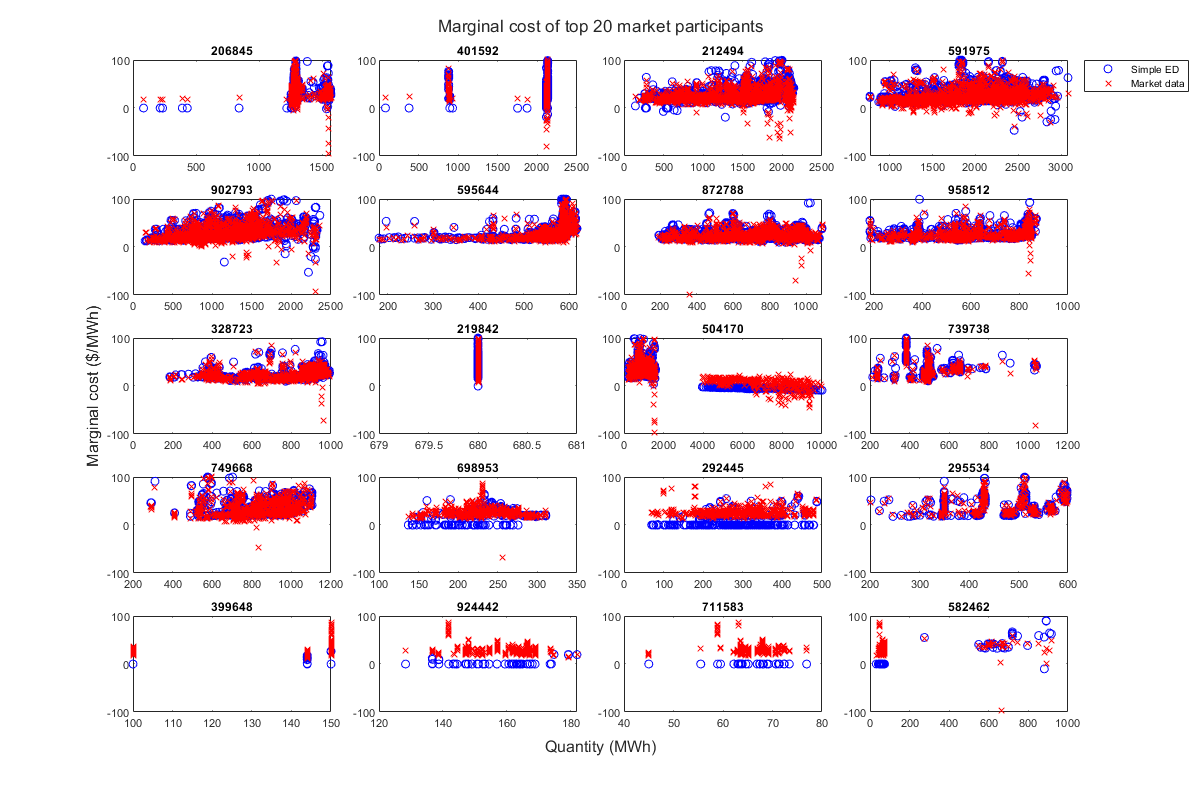

% Plot quantity vs marginal cost of top 20 market participants
plotColumn = 4;
t = tiledlayout(numTopParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numTopParts
    nexttile;
    partQMCTable = topPartQMCTables{n};
    partID = topPartIDs(n);
    % Marginal cost calculated using price from simple economic dispatch
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    % Marginal cost calculated using price from ISONE historical data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-100, 100]);
    if n==plotColumn
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of top 20 market participants");
set(gcf, "Position", [50, 50, 1200, 800]);

### Select top market participants based on their marginal cost distribution

%                      1  2  3  4  5  6  7  8  9 10 11 12 13 14 15 16 17 18 
selPartMask = logical([0; 0; 1; 1; 1; 1; 1; 1; 1; 0; 0; 0; 1; 0; 0; 0; 0; 0; 0; 0]);
selPartIDs = topPartIDs(selPartMask);
selPartQMCTables = topPartQMCTables(selPartMask);
numSelParts = size(selPartIDs, 1);
% selPartIDs = [212494; 591975; 902793; 595644; 872788; 958512; 328723; 739]

### Plot marginal cost distribution of selected market participants

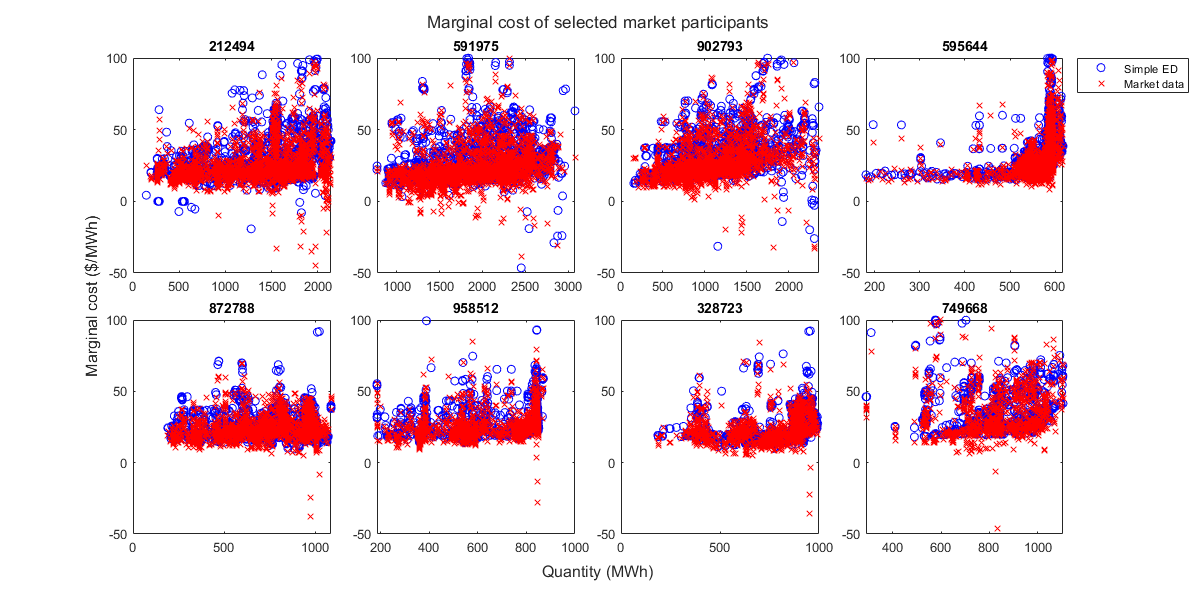

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partQMCTable = selPartQMCTables{n};
    partID = selPartIDs(n);
    % Marginal cost calculated using price from simple economic dispatch
    scatter(partQMCTable.Awarded, partQMCTable.MCSimpleED, 'bo');
    hold on;
    % Marginal cost calculated using price from ISONE historical data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-50, 100]);
    if n==plotColumn
        legend(["Simple ED", "Market data"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Marginal cost of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);

## Marginal cost data cleaning

### Remove outliers using moving median technique

selCleanedPartQMCTables = cell(numSelParts, 1);
for n=1:numSelParts
    partQMCTable = selPartQMCTables{n};
    partID = selPartIDs(n);
    % Calculate the median marginal cost at each quantity
    MCStats = groupsummary(partQMCTable, "Awarded", "median", "MCMarket");
    [cleanedMedian,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(MCStats.median_MCMarket, ...
        'linear','movmedian',300,'SamplePoints',MCStats.Awarded);
    MCStats.cleanedMedian_MCMarket = cleanedMedian;
    QMCTable = innerjoin(MCStats, partQMCTable,"Keys", "Awarded", "LeftVariables", ...
        ["Awarded", "median_MCMarket", "cleanedMedian_MCMarket"], "RightVariables", ["MCMarket", "Date", "Hour"]);
    % Remove marginal cost data with high deviation from the median
    MCDeviation = QMCTable.MCMarket - QMCTable.cleanedMedian_MCMarket;    
    lowPercent = 20;
    highPercent = 80;
    [hOut,hLow,hHigh,~] = isoutlier(MCDeviation,"percentiles", [lowPercent, highPercent]); 
    cleanedQMCTable = QMCTable(~hOut, :);
    selCleanedPartQMCTables{n} = cleanedQMCTable;
end


### Plot cleaned marginal cost data of selected market participants

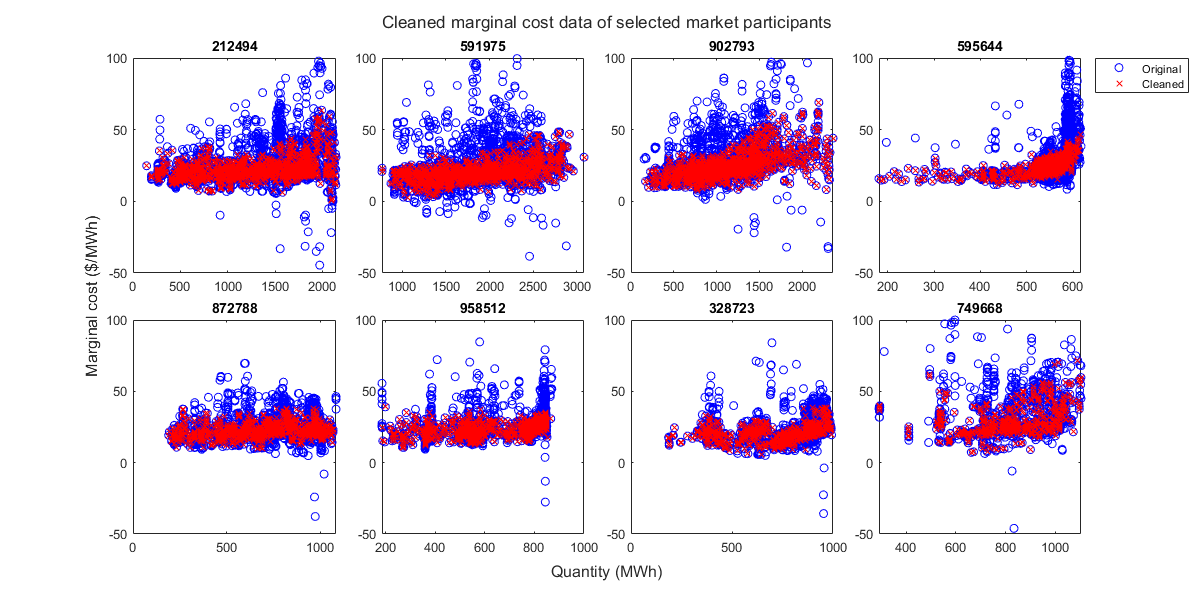

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partQMCTable = selPartQMCTables{n};
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    % Original marginal cost data
    scatter(partQMCTable.Awarded, partQMCTable.MCMarket, 'bo');
    hold on;
    % Cleaned marginal cost data
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 'rx');
    hold off; box on;
    title(partID);
    ylim([-50, 100]);
    if n==plotColumn
        legend(["Original", "Cleaned"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Cleaned marginal cost data of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

## Fit polynomial relation of marginal cost and quantity

### Fit quadratic relations

quadQMC = zeros(numSelParts, 3);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 2);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCQuadFit = y_fit;
    selCleanedPartQMCTables{n}.MCQuadDelta = delta;
    selCleanedPartQMCTables{n}.MCQuadError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCQuadFit;
    quadQMC(n, :) = p;
end

### Fit cubic relations

cubicQMC = zeros(numSelParts, 4);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 3);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCCubicFit = y_fit;
    selCleanedPartQMCTables{n}.MCCubicDelta = delta;
    selCleanedPartQMCTables{n}.MCCubicError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCCubicFit;
    cubicQMC(n, :) = p;
end

### Show fitness of the quadratic and cubic models

corrQuad = zeros(numSelParts, 1);
corrCubic = zeros(numSelParts, 1);
RMSEQuad = zeros(numSelParts, 1);
RMSECubic = zeros(numSelParts, 1);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCQuadFit);
    cubicR = corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCCubicFit);
    corrQuad(n)= quadR(1, 2);
    corrCubic(n) = cubicR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean(partCleanedQMCTable.MCQuadError.^2));
    RMSECubic(n) = sqrt(mean(partCleanedQMCTable.MCCubicError.^2));
end
selPartCorrTable = table(selPartIDs, corrQuad, corrCubic, RMSEQuad, RMSECubic);

### Visualize quadratic and linear relations

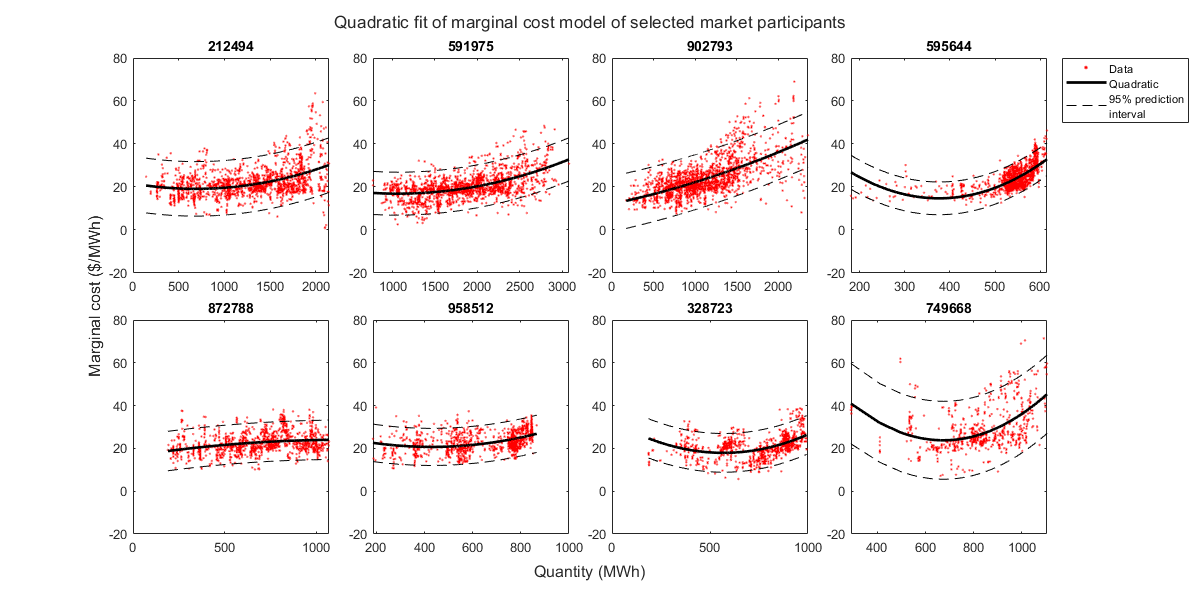

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCQuadFit, 'k-', 'Linewidth', 2);
    quadUpper = partCleanedQMCTable.MCQuadFit + 2*partCleanedQMCTable.MCQuadDelta;
    quadLower = partCleanedQMCTable.MCQuadFit - 2*partCleanedQMCTable.MCQuadDelta;
    plot(partCleanedQMCTable.Awarded, quadUpper, 'k--', partCleanedQMCTable.Awarded, quadLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Quadratic", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Quadratic fit of marginal cost model of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

### Visualize quadratic and linear relations

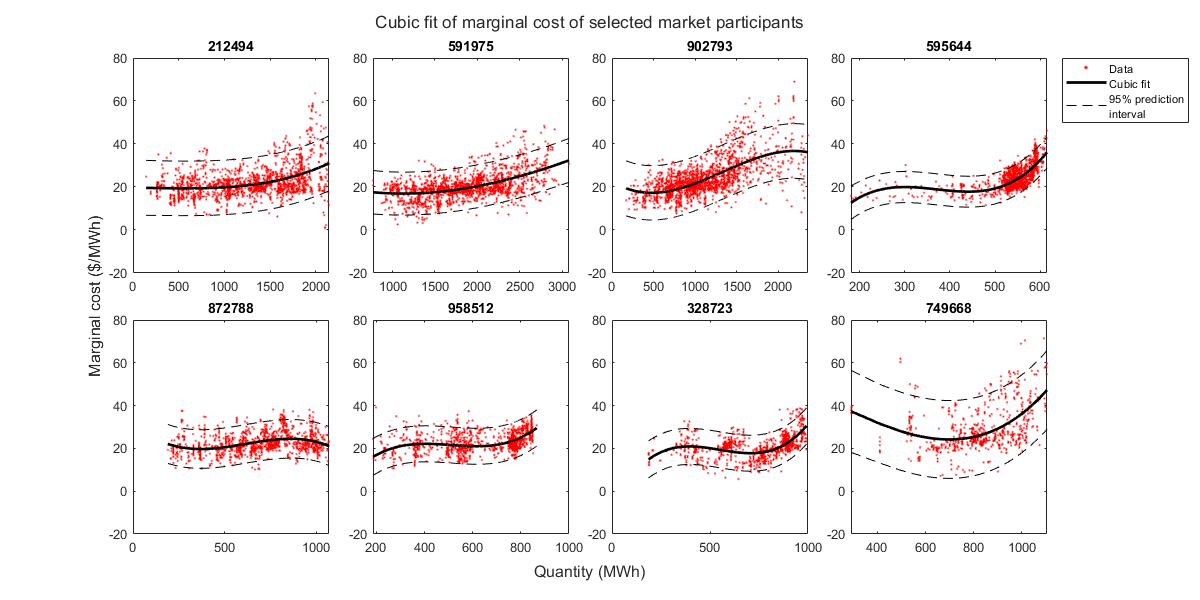

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot cubic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCCubicFit, 'k-', "LineWidth", 2);
    cubicUpper = partCleanedQMCTable.MCCubicFit + 2*partCleanedQMCTable.MCCubicDelta;
    cubicLower = partCleanedQMCTable.MCCubicFit - 2*partCleanedQMCTable.MCCubicDelta;
    plot(partCleanedQMCTable.Awarded, cubicUpper, 'k--', partCleanedQMCTable.Awarded, cubicLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Cubic fit", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Cubic fit of marginal cost of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

## Write cleaned maginal cost data and fitted results to file

% You have to run this under model_code directory
save("selCleanedPartQMCTables.mat", "selCleanedPartQMCTables", "-mat")